# Exercise H3:

clear all; clc; close all;

Solution with 5 points:

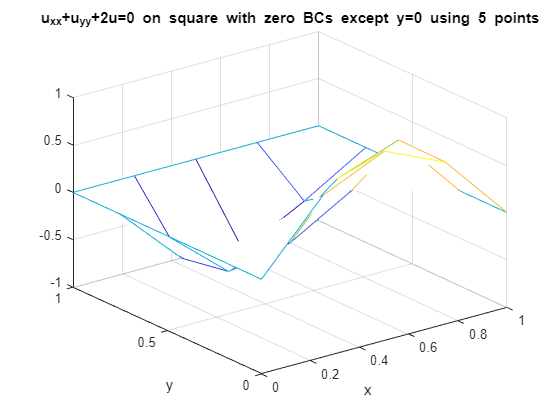

numpts = 5;
[xnew,ynew,sol_new] = FD_2D_func(numpts);


figure; 
mesh(xnew,ynew,sol_new);
xlabel('x')
ylabel('y')
title(['u_{xx}+u_{yy}+2u=0 on square with zero BCs except y=0 using ' num2str(numpts) ' points'])

Then we can see the solution with 20 points

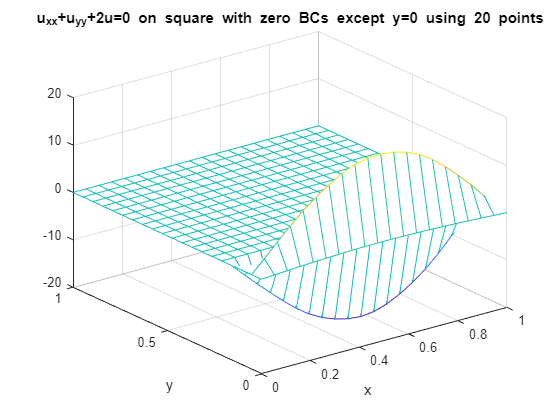

%% 20 points
numpts = 20;
[xnew,ynew,sol_new] = FD_2D_func(numpts);


figure; 
mesh(xnew,ynew,sol_new);
xlabel('x')
ylabel('y')
title(['u_{xx}+u_{yy}+2u=0 on square with zero BCs except y=0 using ' num2str(numpts) ' points'])

And with 60 points

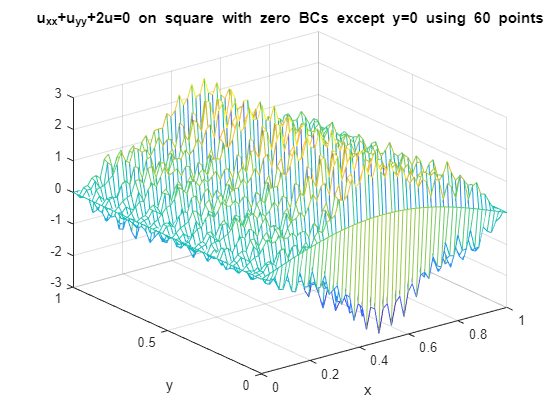

%% 60 points
numpts = 60;
[xnew,ynew,sol_new] = FD_2D_func(numpts);


figure; 
mesh(xnew,ynew,sol_new);
xlabel('x')
ylabel('y')
title(['u_{xx}+u_{yy}+2u=0 on square with zero BCs except y=0 using ' num2str(numpts) ' points'])

The solution seems to get unstable with a finer grid. But I did not plot the true solution compared to the numerical solution to be sure of this. 

Let's define a function to help us try different point easily:

function [x,y,sol] = FD_2D_func(numpts)
N = numpts; % number of grid points in x and y directions, same in both.
m = N - 2; % number of interior points

% -------------------------------------------------------------------------
% Define the grid:
% -------------------------------------------------------------------------
x1 = 0;
xN = 1;
y1 = 0;
yN = 1;
% -------------------------------------------------------------------------
% Determine the stepsize:
% -------------------------------------------------------------------------
h       = (xN-x1)/(N-1);
% -------------------------------------------------------------------------
% We'll just use the same stepsize in x and y 
% Build the xvector of grid points:
% -------------------------------------------------------------------------
x       = x1:h:xN;
y       = y1:h:yN;
% -------------------------------------------------------------------------
% Define the solution matrix and plug in BCs.
% -------------------------------------------------------------------------
sol_FD         = zeros(N,N);
sol_FD(:,1)    = 0; % Enforcing the left side is u=0
sol_FD(:,end)  = 0; % Enforcing right side u=0
sol_FD(end,:)  = 0; % Enforcing the top u=0
sol_FD(1,:)    = sin(pi*x); % Enforcing the bottom BC u(x,0)=sin(pi*x)
% -------------------------------------------------------------------------
% -------------------------------------------------------------------------
% Build the matrix A:
% -------------------------------------------------------------------------
e=1*(ones(m^2-1,1));
ind = 1:m^2-1;
mth_sup_adj = e.*(mod(ind,3)~=0)'; % since every third one should be 0
% Build the main structure of the matrix
A = -2*eye(m^2,m^2) ...  % places -4 on the main diagonal
    + 1*diag(mth_sup_adj,1) ... % Places the adjusted ones on the superdiagonal
    + 1*diag(mth_sup_adj,-1) ... % Places the adjusted ones on the subdiagonal 
    + 1*diag(ones(m^2-m,1),m) ... % Places ones on the mth superdiagonal (no adjustments needed for this.
    + 1*diag(ones(m^2-m,1),-m);  % Places ones on the mth subdiagonal (no adjustments needed for this.

% -------------------------------------------------------------------------
% Build the RHS vector
% -------------------------------------------------------------------------
RHS_vec     = zeros(m^2,1);
% Adjust the entries that have the BCs in them 1, m+1, 2*m+1, etc.  Note
% that the book uses a different ordering of the EQUATIONS that is not as 
% directly compatible with the (:) notation.

for k=1:m
    RHS_vec((k-1)*m + 1)  = -sol_FD(1,k);
end

% -------------------------------------------------------------------------
% Solve for the solution at the interior points
% -------------------------------------------------------------------------
u_interior                      = A\RHS_vec(:);
u_interior                      = reshape(u_interior,m,m); 
sol_FD(2:(end-1),2:(end-1))     = u_interior;
sol = sol_FD;
end